if ~exist('model_base','var')
    load('model_base.mat')
end
% initConfig = model.homeConfiguration;
% show(model, initConfig); 
initBaseConfig = model_base.homeConfiguration;
if ~exist('angleSignal','var')
    load('angleSignal.mat')
end

% left_foot=out.left_foot;
% save('left_foot.mat', 'left_foot');
% right_foot=out.right_foot;
% save('right_foot.mat', 'right_foot');

if ~exist('left_foot','var')
    load('left_foot.mat')
end
if ~exist('right_foot','var')
    load('right_foot.mat')
end

left_foot

left_foot = struct with fields:
     ankleroll_arduino_angle: [1×1 timeseries]
    anklepitch_arduino_angle: [1×1 timeseries]
          knee_arduino_angle: [1×1 timeseries]
      hippitch_arduino_angle: [1×1 timeseries]
       hiproll_arduino_angle: [1×1 timeseries]
        hipyaw_arduino_angle: [1×1 timeseries]


left_foot.ankleroll_arduino_angle

  timeseries

  Common Properties:
            Name: 'ankleroll_arduino_angle'
            Time: [73x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [73x1 int16]
        DataInfo: 

% Create Model Struct
% Create Estimation Data Bus for Simulink Model
left_foot_info = Simulink.Bus.createObject(left_foot);
left_foot_bus = evalin('base', left_foot_info.busName);
right_foot_info = Simulink.Bus.createObject(right_foot);
right_foot_bus = evalin('base', right_foot_info.busName);
robot_time = left_foot.ankleroll_arduino_angle.time

robot_time =          0
    0.0450
    0.0900
    0.1350
    0.1800
    0.2250
    0.2700
    0.3150
    0.3600
    0.4050


startup_dur = 1;
tSingleSupport=0.825;
double_support_ratio=0.725;

time estimate for repetition:

1 second in beginning then 0.725*0.8250. then 0.8250 to take one step

startup_signal=startup_dur+double_support_ratio*tSingleSupport+tSingleSupport

startup_signal = 2.4231

tSingleSupport*2

ans = 1.6500

so basically after startup_signal seconds, the pattern repeats every 2*tSingleSupport seconds. let's verify

left_foot_ankleroll.time=[ ];
left_foot_ankleroll.signals.values=left_foot.ankleroll_arduino_angle.Data;
left_foot_ankleroll.signals.dimensions=1;
left_foot_anklepitch.time=[ ];
left_foot_anklepitch.signals.values=left_foot.anklepitch_arduino_angle.Data;
left_foot_anklepitch.signals.dimensions=1;
left_foot_knee.time=[ ];
left_foot_knee.signals.values=left_foot.knee_arduino_angle.Data;
left_foot_knee.signals.dimensions=1;
left_foot_hippitch.time=[ ];
left_foot_hippitch.signals.values=left_foot.hippitch_arduino_angle.Data;
left_foot_hippitch.signals.dimensions=1;
left_foot_hiproll.time=[ ];
left_foot_hiproll.signals.values=left_foot.hiproll_arduino_angle.Data;
left_foot_hiproll.signals.dimensions=1;
left_foot_hipyaw.time=[ ];
left_foot_hipyaw.signals.values=left_foot.hipyaw_arduino_angle.Data;
left_foot_hipyaw.signals.dimensions=1;

right_foot_ankleroll.time=[ ];
right_foot_ankleroll.signals.values=right_foot.ankleroll_arduino_angle.Data;
right_foot_ankleroll.signals.dimensions=1;
right_foot_anklepitch.time=[ ];
right_foot_anklepitch.signals.values=right_foot.anklepitch_arduino_angle.Data;
right_foot_anklepitch.signals.dimensions=1;
right_foot_knee.time=[ ];
right_foot_knee.signals.values=right_foot.knee_arduino_angle.Data;
right_foot_knee.signals.dimensions=1;
right_foot_hippitch.time=[ ];
right_foot_hippitch.signals.values=right_foot.hippitch_arduino_angle.Data;
right_foot_hippitch.signals.dimensions=1;
right_foot_hiproll.time=[ ];
right_foot_hiproll.signals.values=right_foot.hiproll_arduino_angle.Data;
right_foot_hiproll.signals.dimensions=1;
right_foot_hipyaw.time=[ ];
right_foot_hipyaw.signals.values=right_foot.hipyaw_arduino_angle.Data;
right_foot_hipyaw.signals.dimensions=1;

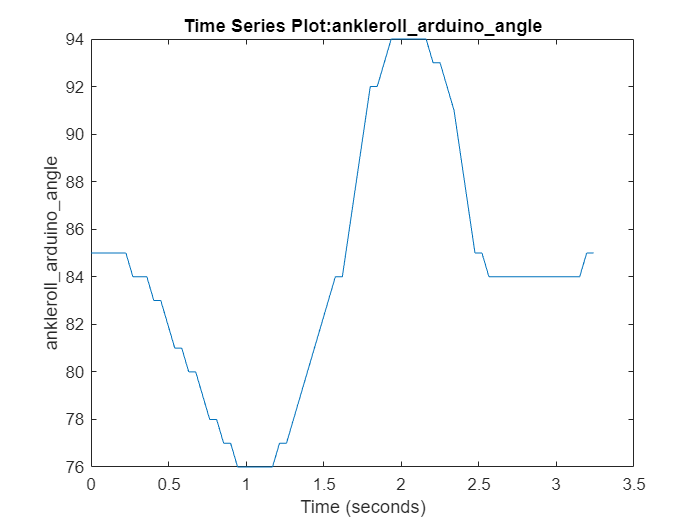

plot(left_foot.ankleroll_arduino_angle)

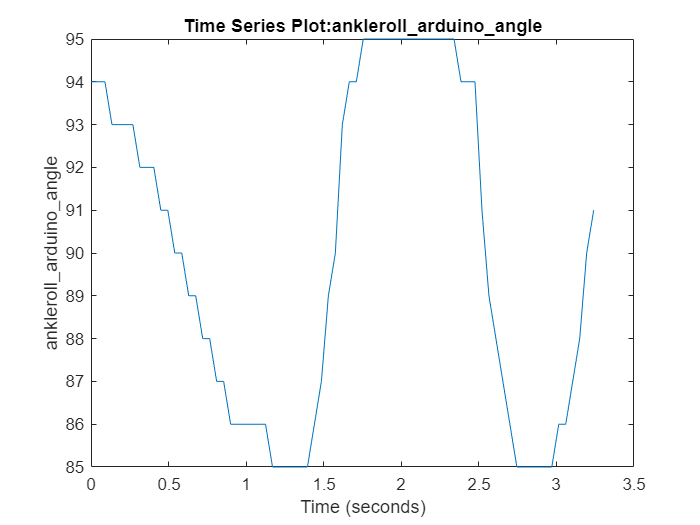

plot(right_foot.ankleroll_arduino_angle)

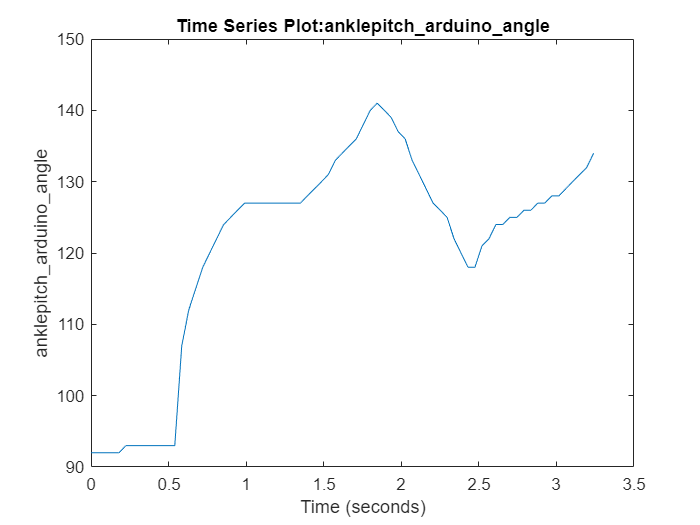

plot(right_foot.anklepitch_arduino_angle)